% Adam Nichols
% Prof. Jacobs
% ECE 1898
% 3 February 2025

% modulate/demodulate a message using a simple OFDM scheme

% reset the workspace
clear, clc

% generate a message of random bits
num_bits = 96;
bits = RandomBits(num_bits);

% parallelize bits into bitstreams
num_carriers = 32;
num_OFDM_symbols = ceil(num_bits / num_carriers);
if mod(num_bits,num_carriers) > 0
    bits_padded = [bits; zeros(num_carriers-mod(num_bits,num_carriers),1)];
else
    bits_padded = bits;
end

OFDM_data = reshape(bits_padded,num_carriers,[]);

% modulate OFDM symbols from the fourier coefficients
fourier_coeffs = OFDM_data*2 - 1;
s_t = zeros(num_carriers,num_OFDM_symbols);
% perform IFFT
for i = 0:num_OFDM_symbols-1
    s_t(i*num_carriers+1:(i+1)*num_carriers) = ifft(fourier_coeffs(i*num_carriers+1:(i+1)*num_carriers));
end

% define timing parameters of the OFDM signal
bandwidth = 1e4;
OFDM_samplerate = bandwidth;
OFDM_sampleperiod = 1/OFDM_samplerate;
OFDM_symboltime = OFDM_sampleperiod * num_carriers;
OFDM_symbolrate = 1/OFDM_symboltime;
t = transpose((0:num_carriers*num_OFDM_symbols-1)*OFDM_sampleperiod);

% perform upsampling
upsamp = 8;
s_t_upsamp = zeros(num_carriers*upsamp,num_OFDM_symbols);
for i = 0:num_OFDM_symbols-1
    s_t_curr = s_t(i*num_carriers+1:(i+1)*num_carriers);
    if num_OFDM_symbols > 1
        s_t_curr = transpose(s_t_curr)
    end
    s_t_curr_triple = [s_t_curr; s_t_curr; s_t_curr];
    s_t_curr_triple_upsamp = resample(s_t_curr_triple,upsamp,1);
    s_t_curr_upsamp = s_t_curr_triple_upsamp(upsamp*num_carriers+1:2*upsamp*num_carriers);

    % s_t_curr_plus_one = [s_t_curr; s_t_curr(1)];
    % s_t_curr_upsamp = resample(s_t_curr_plus_one,upsamp,1);
    % s_t_curr_upsamp = s_t_curr_upsamp(1:end-upsamp);
    s_t_upsamp((i*num_carriers*upsamp+1:(i+1)*num_carriers*upsamp)) = s_t_curr_upsamp;
end

s_t_curr =    0.0000 + 0.0000i
  -0.1443 + 0.1221i
   0.0896 - 0.0530i
   0.1419 - 0.1638i
  -0.2134 + 0.0884i
   0.0136 - 0.0602i
   0.1987 - 0.0147i
  -0.0504 + 0.0150i
   0.1250 + 0.1250i
  -0.1629 - 0.1275i


s_t_curr =   -0.0625 + 0.0000i
   0.2447 + 0.1849i
  -0.1780 - 0.0884i
  -0.2179 + 0.0748i
  -0.0259 - 0.1250i
   0.1024 - 0.0234i
  -0.1103 - 0.0884i
   0.1322 + 0.0116i
   0.0625 + 0.0000i
   0.1696 - 0.2194i


s_t_curr =    0.0625 + 0.0000i
  -0.0975 + 0.0618i
   0.0597 - 0.0338i
  -0.2594 + 0.2017i
   0.0625 + 0.0884i
  -0.1297 - 0.1109i
  -0.0692 + 0.0817i
  -0.1081 - 0.1282i
  -0.0625 - 0.2500i
  -0.1125 + 0.0486i


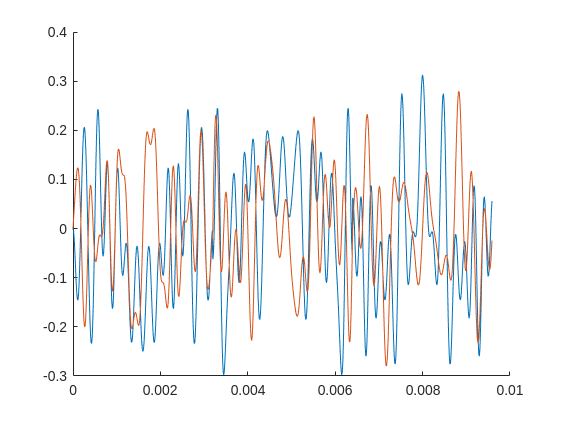

OFDM_samplerate_upsamp = upsamp*OFDM_samplerate;
OFDM_sampleperiod_upsamp = OFDM_sampleperiod/upsamp;
t_upsamp = transpose((0:num_carriers*num_OFDM_symbols*upsamp-1)*OFDM_sampleperiod_upsamp);

% concatenate all OFDM symbols without guard intervals or filtering
s_t_upsamp_vec = reshape(s_t_upsamp,[],1);

% plot this upsampled, concatenated version of OFDM
figure(1)
clf
hold on
plot(t_upsamp,real(s_t_upsamp_vec))
plot(t_upsamp,imag(s_t_upsamp_vec))

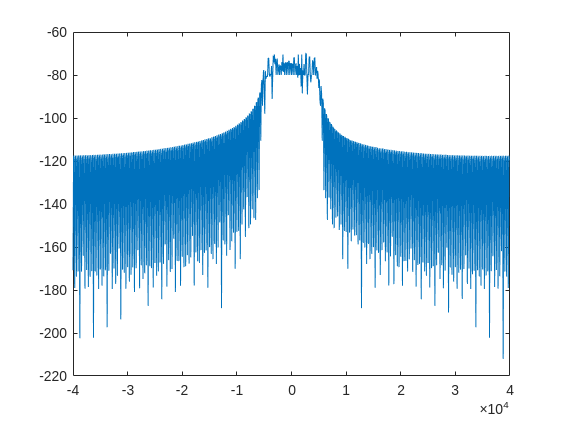


% get the spectrum of the concatednated signal
[f_upsamp_all, spec_upsamp_all] = GetSpectrum(s_t_upsamp_vec,OFDM_samplerate_upsamp);
mag_spec_upsam_all = 20*log10(abs(spec_upsamp_all));

% plot the spectrum of the upsampled signal
figure(2)
clf
plot(f_upsamp_all,mag_spec_upsam_all)


% perform cyclic prefixing to reduce spurious emission

